# Effect of Pole Locations: 1st Order Pole

First let's define the Laplace variable s, which we can use to build transfer functions

s = tf('s');

## Create the transfer function with the pole

Let's define the real part of the pole.

sigma = 6.5;  % real part

The pole is then

$p = \sigma$.

p = sigma;

Try different values of $\sigma$ to see how the system responds.

We will assume the transfer function is


$$G(s) = \frac{1}{s - p}$$


G = 1/(s - p)

G =
 
     1
  -------
  s - 6.5
 
Continuous-time transfer function.



## Show where the pole is on the s-plane

A pole-zero map shows the locations of all of the zeros and all of the poles of a transfer function.  With this we have a picture of whether the poles are in the LHP or RHP.

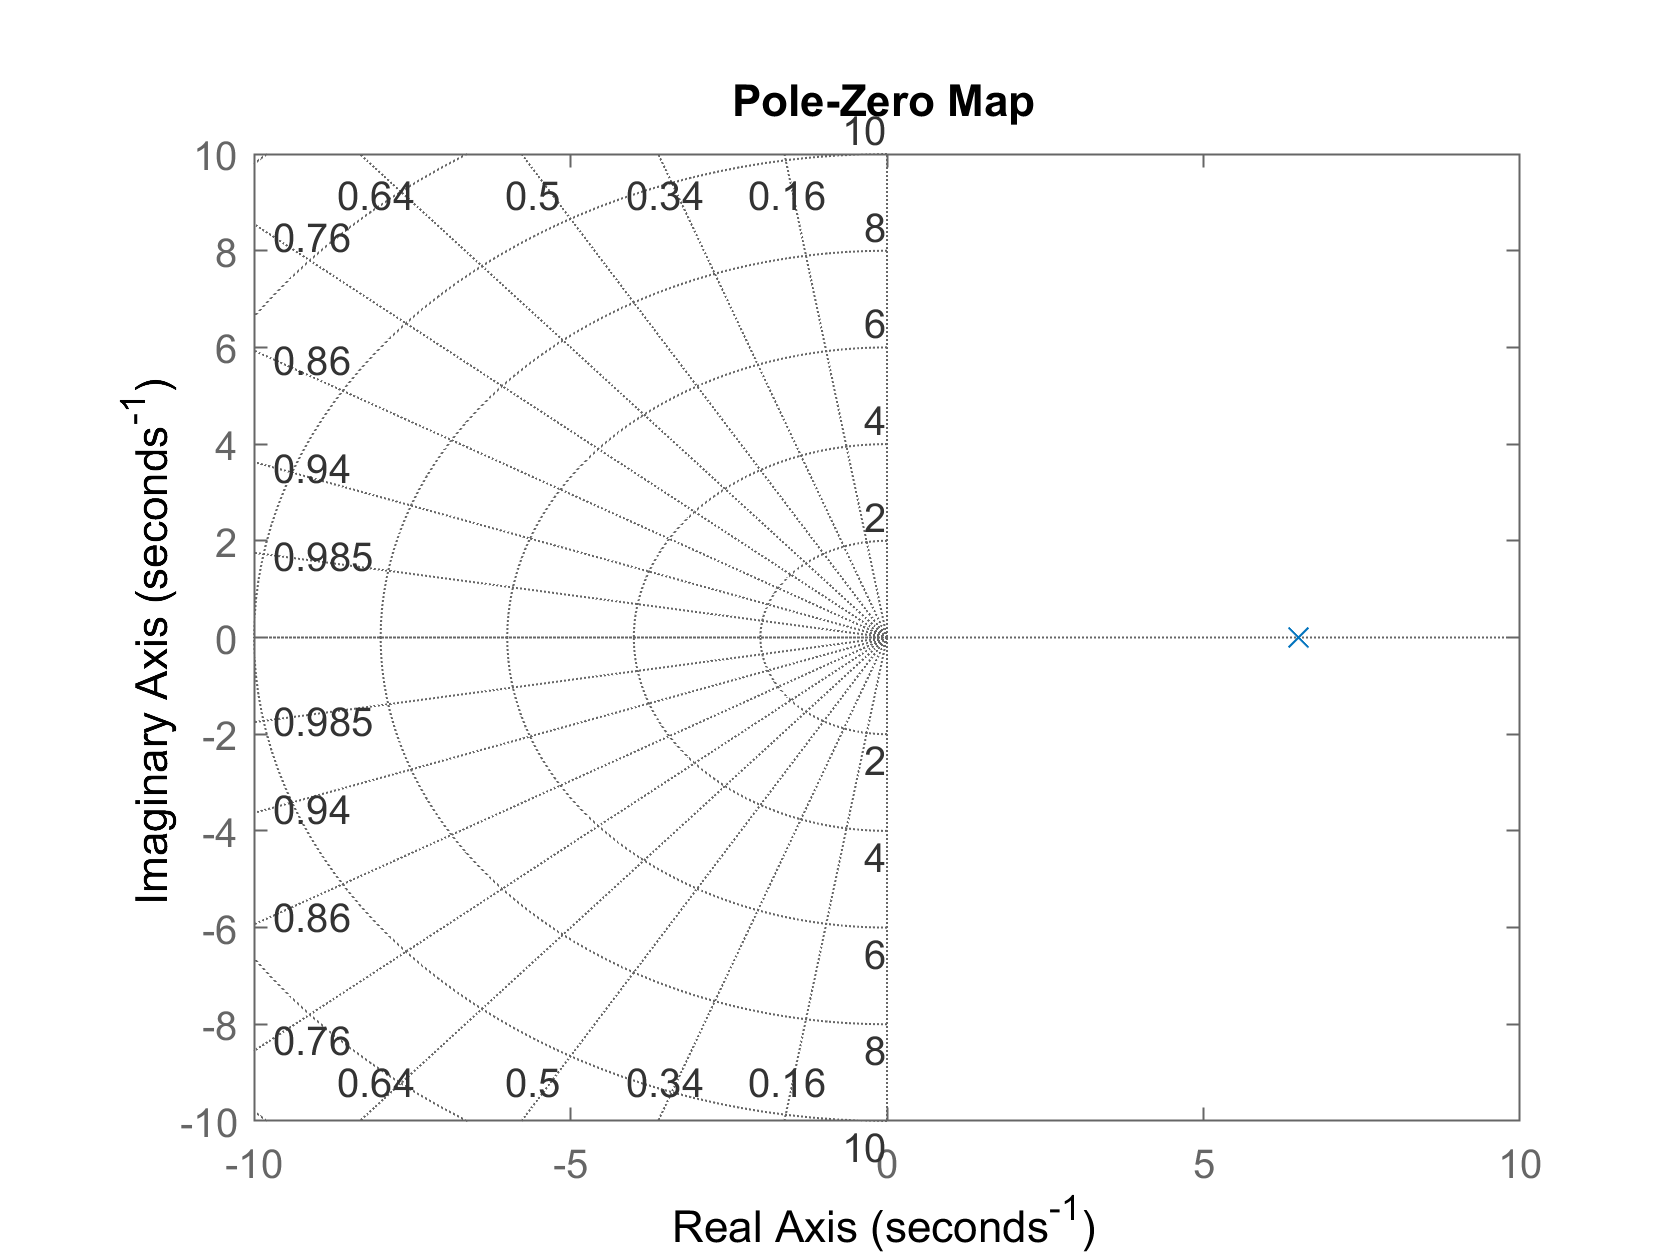

pzplot(G)
axis([-10 10 -10 10])
grid on 

## Look at the impulse response

Now lets look at an impulse response of the system.

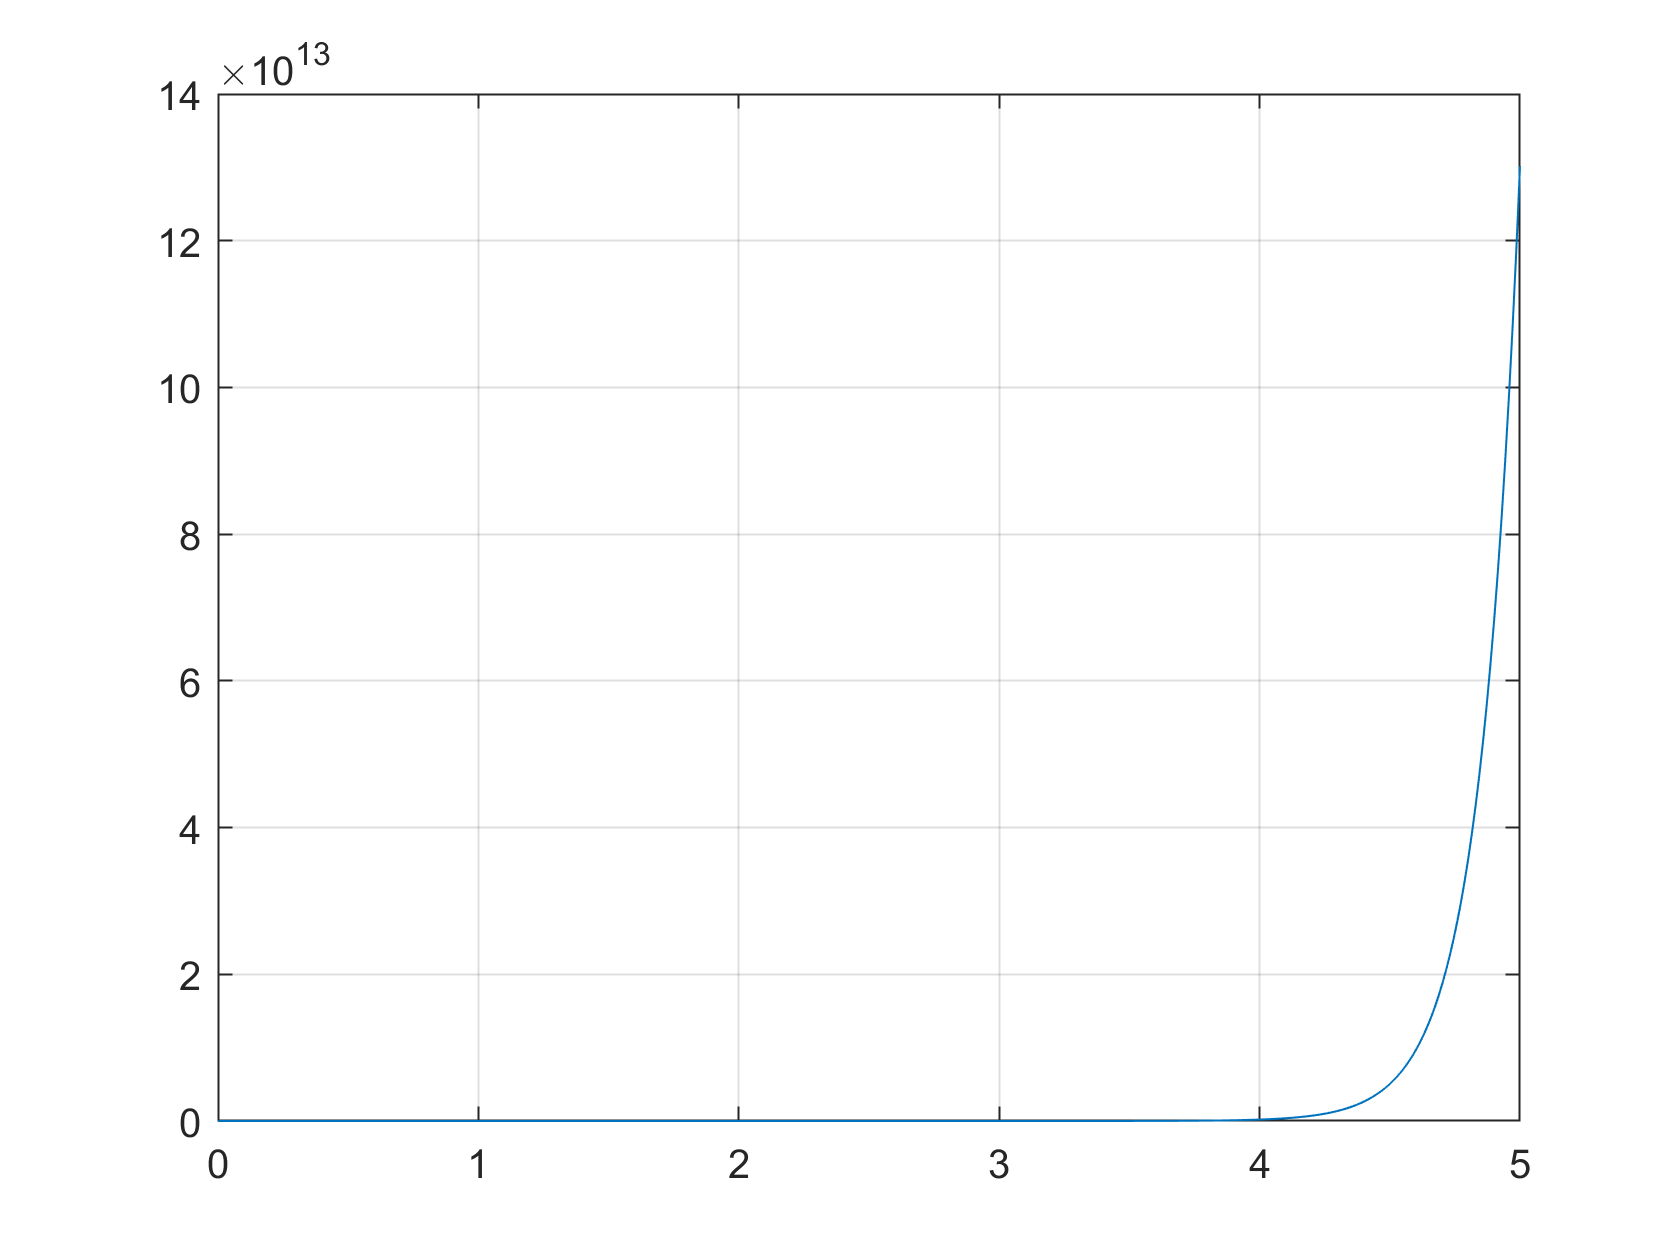

Tfinal = 5;     % the final time of the response
[output,t] = impulse(G,Tfinal);
plot(t,output)
grid on

## Look at the step response

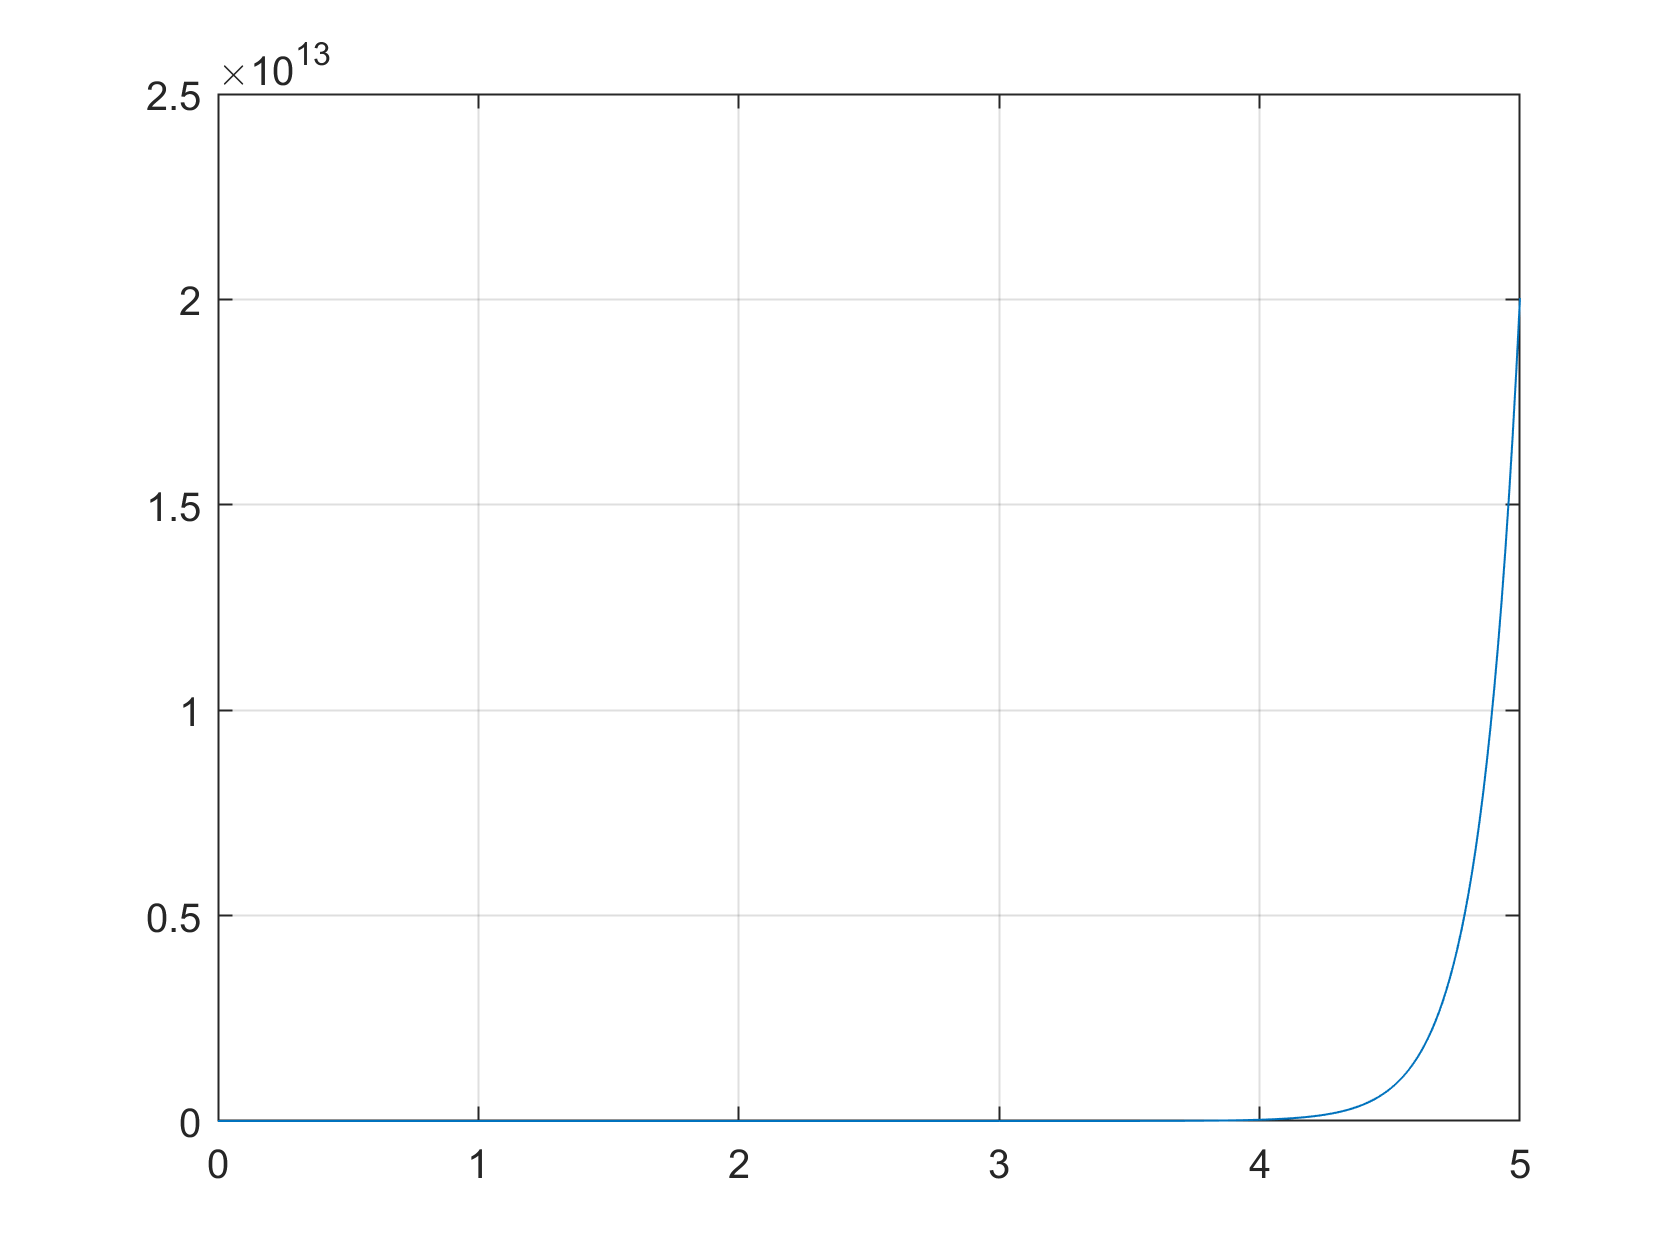

[output,t] = step(G,Tfinal);
plot(t,output)
grid on